# Data Import

In MATLAB, we can do data import in two ways,

- Manual Data Import

- Automatic Data Import

## Manual Data Import

diabetes_data=readtable("Diabetes Missing Data.csv")

diabetes_data = 768x9 table
    Pregnant    Glucose    Diastolic_BP    Skin_Fold    Serum_Insulin    BMI     Diabetes_Pedigree    Age    Class
    ________    _______    ____________    _________    _____________    ____    _________________    ___    _____

        6         148           72             35            NaN         33.6          0.627          50       1  
        1          85           66             29            NaN         26.6          0.351          31       0  
        8         183           64            NaN            NaN         23.3          0.672          32       1  
        1          89           66             23             94         28.1          0.1

## Automatic Data Import

% Import data from text file
DiabetesMissingData = readtable("/MATLAB Drive/VVCE_FDP_OCT2023/Data/Diabetes Missing Data.csv");

% Display results
DiabetesMissingData

DiabetesMissingData = 768x9 table
    Pregnant    Glucose    Diastolic_BP    Skin_Fold    Serum_Insulin    BMI     Diabetes_Pedigree    Age    Class
    ________    _______    ____________    _________    _____________    ____    _________________    ___    _____

        6         148           72             35            NaN         33.6          0.627          50       1  
        1          85           66             29            NaN         26.6          0.351          31       0  
        8         183           64            NaN            NaN         23.3          0.672          32       1  
        1          89           66             23             94         28.1       

## Identify Missing Values

missing_matrix=ismissing(diabetes_data)

missing_matrix = 768x9 logical array
   0   0   0   0   1   0   0   0   0
   0   0   0   0   1   0   0   0   0
   0   0   0   1   1   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   1   1   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   1   1   1   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   1   1   1   0   0   0


missing_values_columnwise=sum(missing_matrix)

missing_values_columnwise =      0     5    35   227   374    11     0     0     0


total_missing_values=nnz(missing_matrix)

total_missing_values = 652

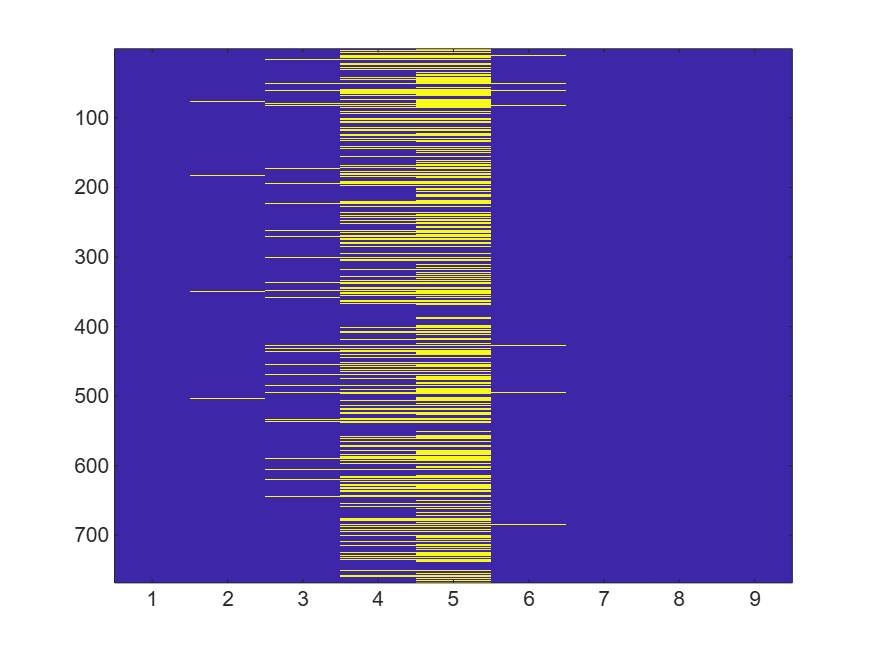

imagesc(missing_matrix)

## Handle the Missing Values

avg_glucose=mean(diabetes_data.Glucose,'omitmissing')

avg_glucose = 121.6868

diabetes_data.Glucose(ismissing(diabetes_data.Glucose))=round(avg_glucose)

diabetes_data = 768x9 table
    Pregnant    Glucose    Diastolic_BP    Skin_Fold    Serum_Insulin    BMI     Diabetes_Pedigree    Age    Class
    ________    _______    ____________    _________    _____________    ____    _________________    ___    _____

        6         148           72             35            NaN         33.6          0.627          50       1  
        1          85           66             29            NaN         26.6          0.351          31       0  
        8         183           64            NaN            NaN         23.3          0.672          32       1  
        1          89           66             23             94         28.1          0.1

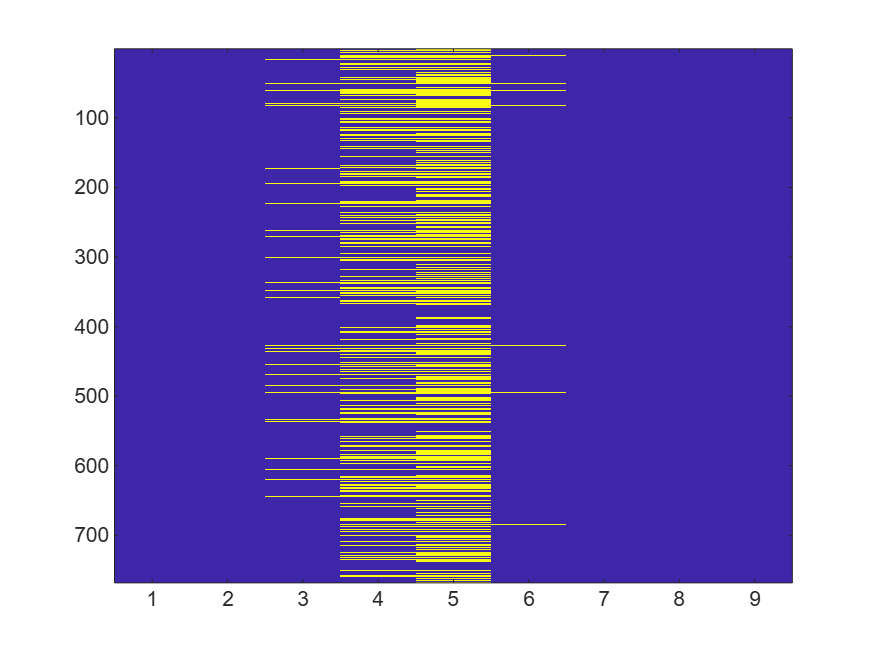

missing_matrix_processed=ismissing(diabetes_data);
imagesc(missing_matrix_processed)

## Automatic Handling of Missing Values

avg_diastolic=round(mean(diabetes_data.Diastolic_BP,'omitmissing'))

avg_diastolic = 72

avg_skinfold=round(mean(diabetes_data.Skin_Fold,'omitmissing'))

avg_skinfold = 29

avg_Insulin=round(mean(diabetes_data.Serum_Insulin,'omitmissing'))

avg_Insulin = 156

avg_BMI=vpa(mean(diabetes_data.BMI,'omitmissing'),3)

$$avg\_BMI = 32.5$$

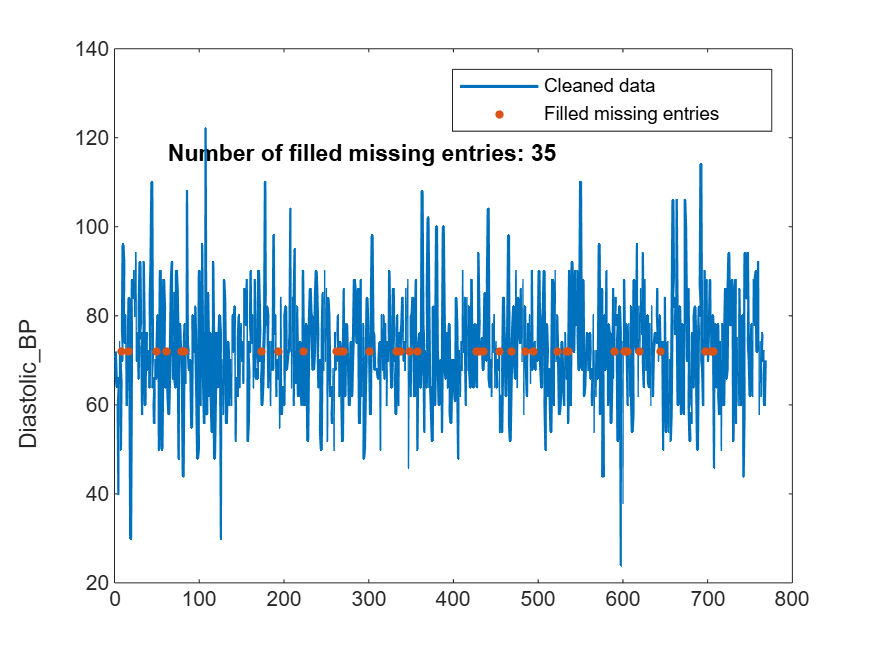

% Fill missing data
[newTable,missingIndices] = fillmissing(diabetes_data,"constant",72, ...
    "DataVariables","Diastolic_BP");

% Display results
figure

% Plot cleaned data
plot(newTable.Diastolic_BP,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices(:,3)),newTable.Diastolic_BP(missingIndices(:,3)),".", ...
    "MarkerSize",12,"SeriesIndex",2,"DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,3)))

hold off
legend
ylabel("Diastolic_BP","Interpreter","none")

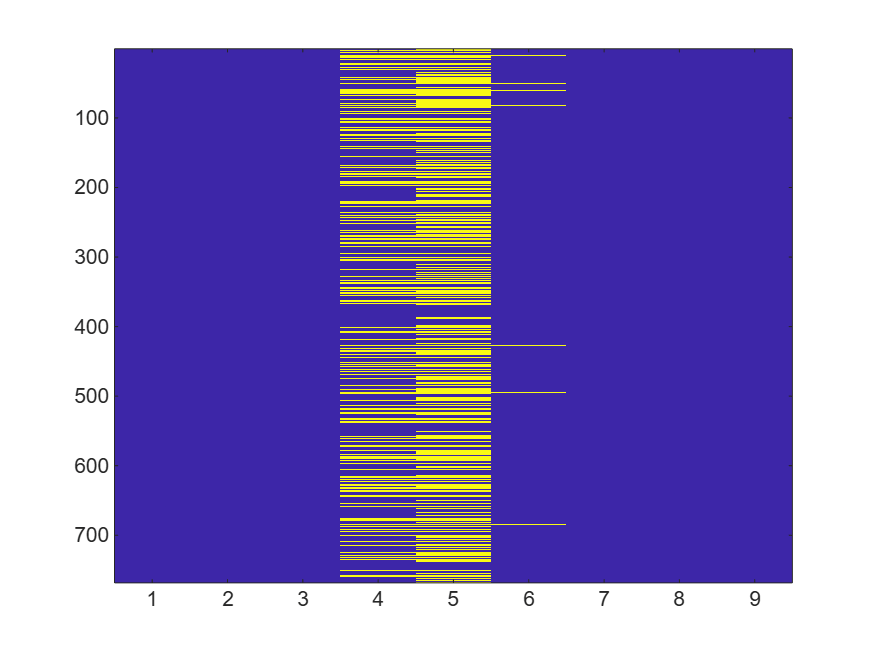

clear missingIndices
imagesc(ismissing(newTable))

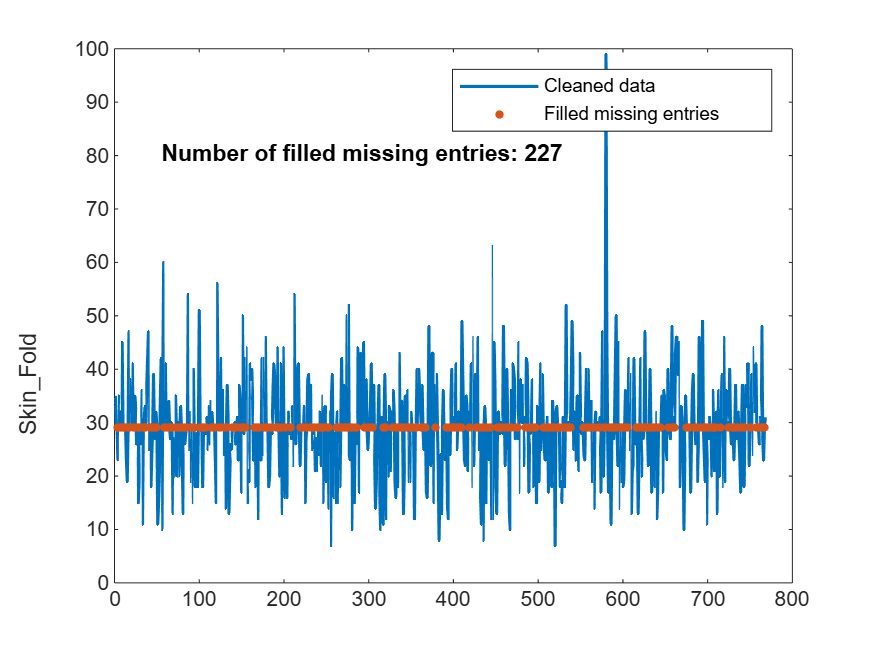

% Fill missing data
[newTable,missingIndices] = fillmissing(newTable,"constant",29, ...
    "DataVariables","Skin_Fold");

% Display results
figure

% Plot cleaned data
plot(newTable.Skin_Fold,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices(:,4)),newTable.Skin_Fold(missingIndices(:,4)),".", ...
    "MarkerSize",12,"SeriesIndex",2,"DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,4)))

hold off
legend
ylabel("Skin_Fold","Interpreter","none")

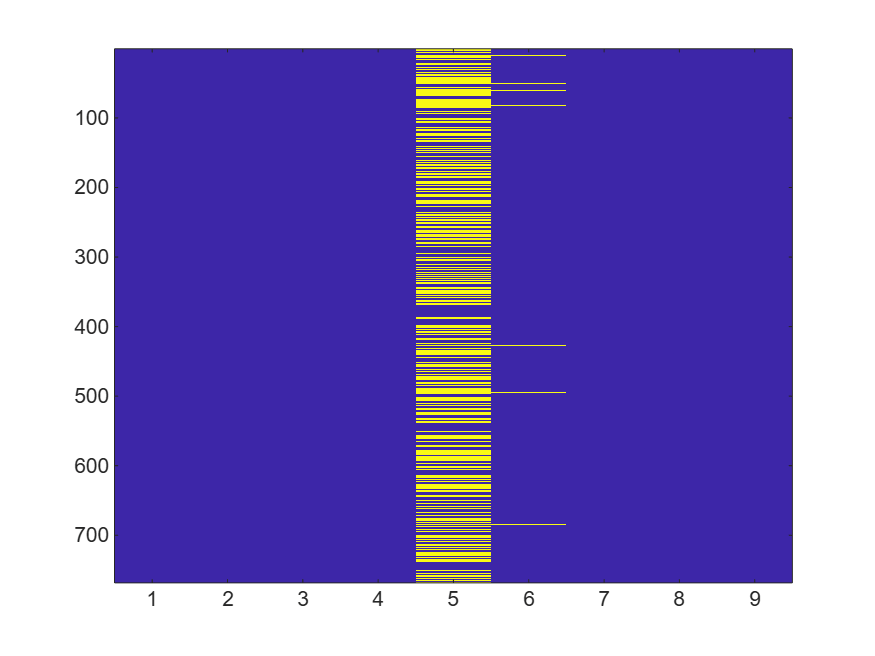

imagesc(ismissing(newTable))

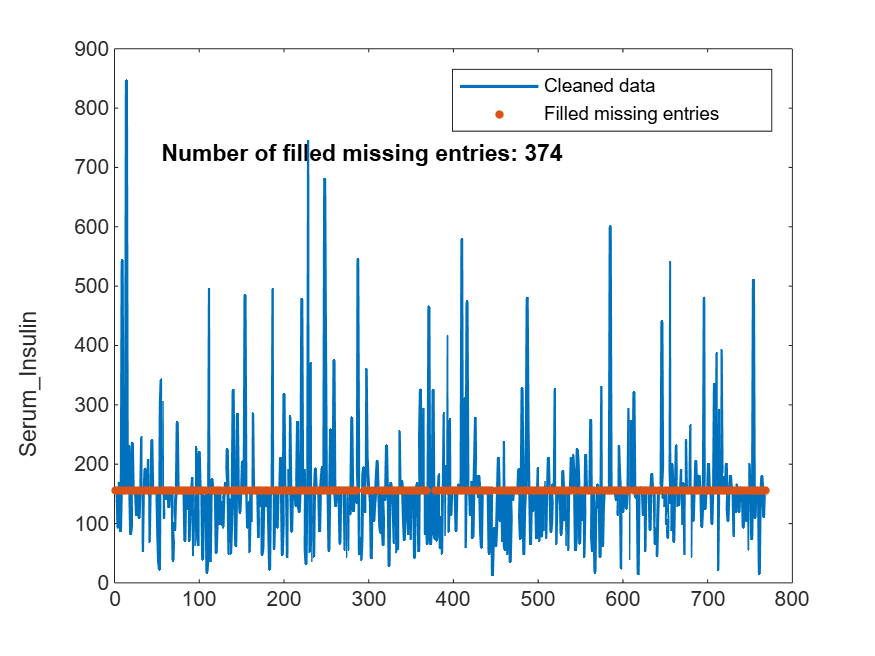

% Fill missing data
[newTable,missingIndices] = fillmissing(newTable,"constant",156, ...
    "DataVariables","Serum_Insulin");

% Display results
figure

% Plot cleaned data
plot(newTable.Serum_Insulin,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices(:,5)),newTable.Serum_Insulin(missingIndices(:,5)),".", ...
    "MarkerSize",12,"SeriesIndex",2,"DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,5)))

hold off
legend
ylabel("Serum_Insulin","Interpreter","none")

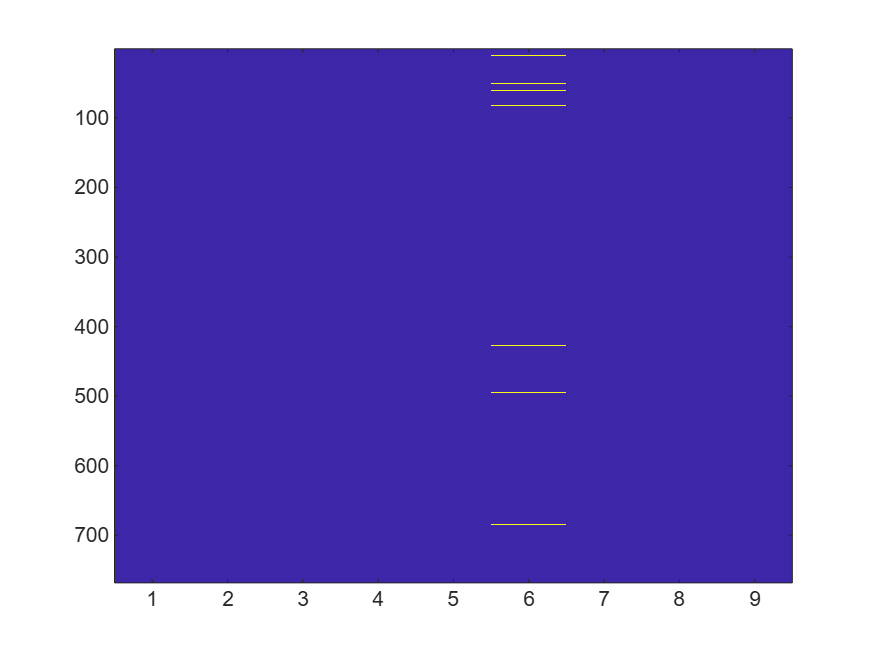

imagesc(ismissing(newTable))

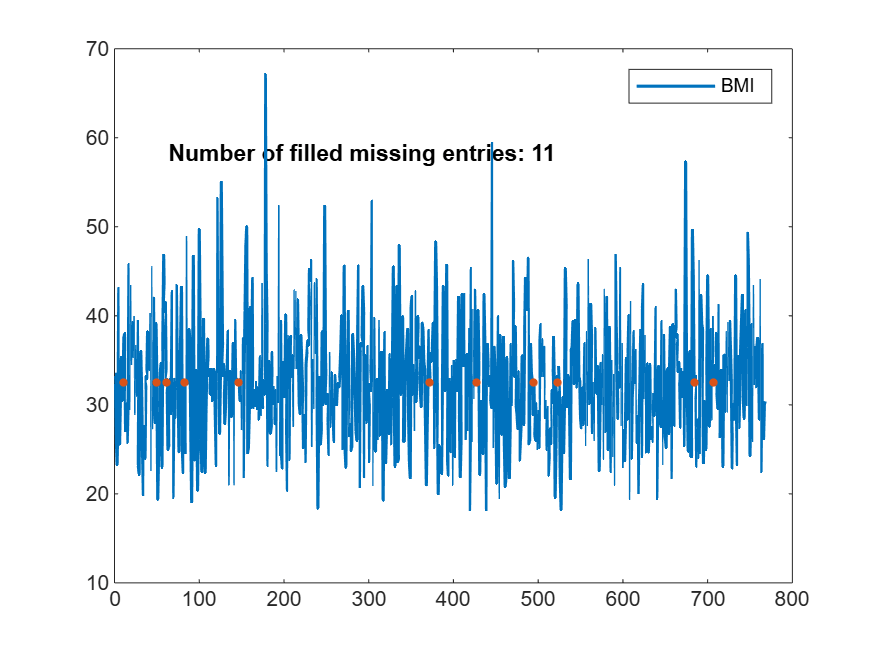

% Fill missing data
[newTable,missingIndices] = fillmissing(newTable,"constant",32.5000, ...
    "DataVariables","BMI");

% Display results
figure

% Plot cleaned data
plot(newTable.BMI,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices(:,6)),newTable.BMI(missingIndices(:,6)),".", ...
    "MarkerSize",12,"SeriesIndex",2,"DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,6)))

hold off
legend("BMI","Interpreter","none")

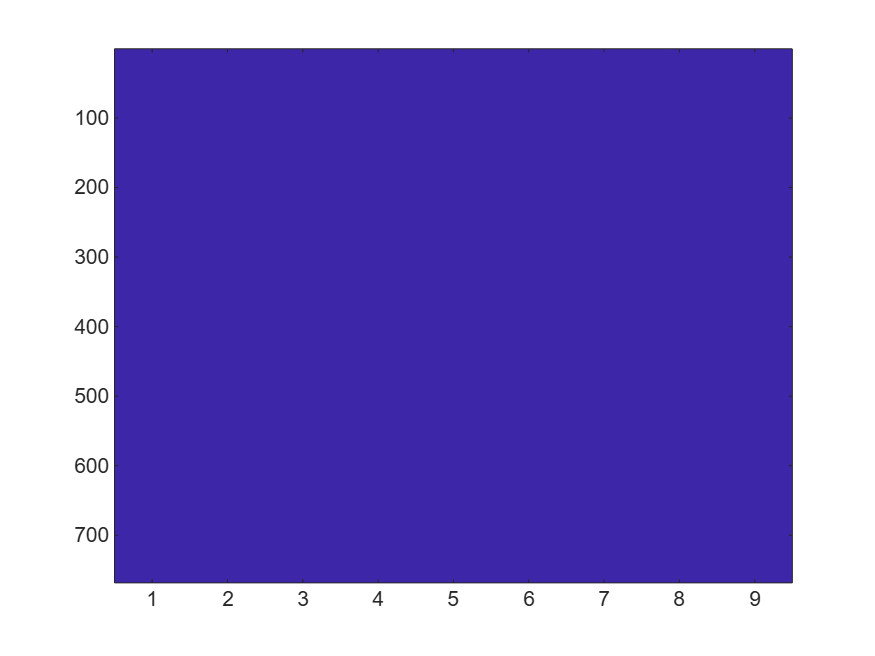

imagesc(ismissing(newTable))